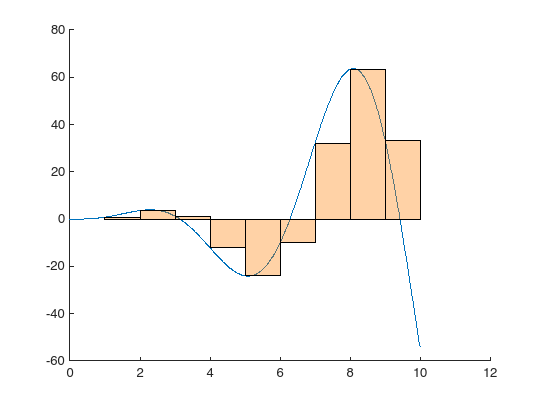

clear

warning('off', 'MATLAB:polyshape:repairedBySimplify')
warning('off', 'MATLAB:polyshape:boolOperationFailed')


startX = 0;
endX = 10;

h = 1;

X = startX:h:endX;
Y = f(X);

miniH = h * 0.01;
miniX = startX:miniH:endX;
miniY = f(miniX);

hold on
plot(miniX, miniY)


for i = 1:length(X)-1
%     rectangle('Position', [X(i), 0, X(i+1)-X(i), Y(i)], 'FaceColor', [1, 0.5, 0])
    plot(polyshape([X(i), X(i), X(i+1), X(i+1)], [0, Y(i), Y(i), 0]), 'FaceColor', [1, 0.5, 0])
    pause
end

function f = f(X)
    f = X.^2 .* sin(X);
end